addpath(genpath(pwd));
addpath('./HelperFunctions');
warning off;                      % suprress warning messages

## Prepare to read the data into memory

To load the recordings into memory, MATLAB's [fileDatastore](https://www.mathworks.com/help/matlab/ref/filedatastore.html) provides a convenient way to handle a large number of data files spread across multiple folders. The read function provides flexibility to access a wide variety of different file formats, and with MATLAB's base read functions typically little customization is needed. 

training_fds = fileDatastore(fullfile(pwd, 'original_data'), 'ReadFcn', @load, 'FileExtensions', '','IncludeSubfolders',true);


## Create a table with filenames and labels

data_dir = fullfile(pwd, 'original_data');
folder_list = dir([data_dir filesep 'train*']);

for ifolder = 1:length(folder_list)
     disp(['Processing files from folder: ' folder_list(ifolder).name])
    current_folder = [data_dir filesep folder_list(ifolder).name];
end


## Extract features from raw heart sound signals

runExtraction = true; % control whether to run feature extraction (will take several minutes)
   % Note: be sure to have the training data downloaded before executing
   % this section!
if runExtraction | ~exist('FeatureTable.mat')%#ok 
    % Window length for feature extraction in seconds
    win_len = 4;
    
    % Specify the overlap between adjacent windows for feature extraction in percentage
    win_overlap = 0;
    
    % Initialize feature table to accumulate observations
    feature_table = table();
    %test_set = table();
    % Use Parallel Computing Toobox to speed up feature extraction by distributing computation across available processors
    
    % Create partitions of the fileDatastore object based on the number of processors
    n_parts = numpartitions(training_fds, gcp);
    %n_parts = numpartitions(validation_fds, gcp);

    
    % Note: You could distribute computation across available processors by using 
    % parfor instead of "for" below, but you'll need to omit keeping track
    % of signal lengths
    sig_length=[];
    count=0;
    old_name='';
    position=0;
   for ipart = 1:n_parts
        % Get partition ipart of the datastore.
        subds = partition(training_fds, n_parts, ipart);
        %subds = partition(validation_fds, n_parts, ipart);


        % Extract features for the sub datastore
%         [feature_win,sampleN] = extractFeatures_inhale_exhale(subds, win_len, win_overlap, reference_table,quality_of_sound);
%         feature_win = extractQ(subds,quality_of_sound);

        [feature_win, old_name, position]= extractFeatures_s(subds,win_len,win_overlap,old_name,position);

        count=count+1;
%         sig_length=[sig_length; sampleN];
        % and append that to the overall feature table we're building up
        
        feature_table = [feature_table; feature_win];
        %test_set = [test_set; feature_win];
        % Display progress
        disp(['Part ' num2str(ipart) ' done.'])
    end
    save('FeatureTable', 'feature_table');
    %save('test_set', 'test_set');

else % simply load the precomputed features
    load('FeatureTable.mat');
end

feature_table_filtered = feature_table;
% 
% feature_table_infra_16 = feature_table;
% feature_table_infra_infra = feature_table_infra;
% feature_table_infra_no_infra = feature_table_infra;
% feature_table_noninfra = feature_table;

Part 1 done.
Part 2 done.
Part 3 done.
Part 4 done.
Part 5 done.
Part 6 done.
Part 7 done.
Part 8 done.
Part 9 done.
Part 10 done.
Part 11 done.
Part 12 done.


% feature_table_infra = feature_table;
% 
% ind1 = find(feature_table.position==1);
% ind2 = find(feature_table.position==2);
% ind5 = find(feature_table.position==5);
% ind4 = find(feature_table.position==4);
% 
% feature_table_3 = feature_table([12227:14278,15460:end],:);
% median0_feature_table_infra=varfun(@median0,feature_table,'GroupingVariables',{'name','position','class'});
% median0_feature_table_noninfra=varfun(@median0,feature_table_infra,'GroupingVariables',{'name','position','class'});
median0_feature_table_filtered=varfun(@median0,feature_table_filtered,'GroupingVariables',{'name','position','class'});
% median0_feature_table=varfun(@median0,feature_table,'GroupingVariables',{'name','position','class'});
% 
% 
% ind_back = find(median0_feature_table_infra.position>6);
% [idx,scores] = fscmrmr(median0_feature_table_infra(ind_back,5:end),median0_feature_table_infra(ind_back,3));
% idx_select = unique([idx(1:50)]);
% median0_feature_table_infra_select = median0_feature_table_infra(:,[1,2,3,idx_select+4]);
% 
% 
% median0_feature_table=varfun(@median0,feature_table,'GroupingVariables',{'name','class'});
% 
% training_set = feature_table(1:3153,:);
% test_set = feature_table(3154:end,:);
% classifyResult = trainedModel.predictFcn(test_set);
% 
% 
% feature_table_front = feature_table(find(feature_table.position<7),:);
% feature_table_back = feature_table(find(feature_table.position>6),:);
% feature_table_back = feature_table_back(find(feature_table_back.position<13),:);
% 
% 
% median0_feature_table_front=varfun(@median0,feature_table_front,'GroupingVariables',{'name','class'});
% median0_feature_table_front_selected = median0_feature_table_front([1,2,3,6,11,12,15,38:86],:);
% median0_feature_table_front.normMFCC1 = (median0_feature_table_front.median0_MFCC1-51)./median0_feature_table_front.median0_meanValue;
% mean0_feature_table=varfun(@mean0,feature_table,'GroupingVariables',{'name','class'});
% 
% median0_feature_table=varfun(@median0,feature_table,'GroupingVariables',{'name','class'});
% median0_feature_table_back=varfun(@median0,feature_table_back,'GroupingVariables',{'name','class'});
% 
% ind_=[4,5,8,63];
% rate_table = feature_table(:,ind_);
% 
% num_of_zeroes=varfun(@zerocount,rate_table,'GroupingVariables',{'name','class'});
% 
% median0_feature_table_infra.Properties.VariableNames;
% feature_table.Properties.VariableNames;
% 
% feature_table10=feature_table([find(feature_table.class==1); find(feature_table.class==3)],:);
% feature_table10=feature_table(strcmp(feature_table.class,'Pneumonia'),:);
% 
% sortedTable = sortrows(feature_table, 2);

quan25 = @(x) quantile(x, 0.25);
quan75 = @(x) quantile(x, 0.75);

% new_feature_table=feature_table;
% for i=1:size(new_feature_table,1)
%     if strcmp(new_feature_table.class{i},'Normal')
%         new_feature_table.name{i}= [new_feature_table.name{i} num2str(i)];
%     end
% end
% 
% feature_table_hilbert=feature_table;
% 
% feature_table_COPD_infra=feature_table;
% feature_table_COPD_200=feature_table;
% 
% test_set=sortedTable(2235:end,:);
% training_set=sortedTable(1:2234,:);

% count_COPD=0;
% count_COPD_with_Q=0;
% COPD_feature_table=table();
% for i=1:size(feature_table,1)
%     if strcmp(feature_table.class(i),'COPD')
%         count_COPD=count_COPD+1;
%         list_of_COPD_names(count_COPD)=feature_table.name(i);
%         if feature_table.Q(i)>20
%             count_COPD_with_Q=count_COPD_with_Q+1;
%             COPD_with_Q_feature_table(count_COPD_with_Q,:)=feature_table(i,:);
%         end
%     end
% end

% list_of_COPD_names=list_of_COPD_names';
% 
% quan25_feature_table_200=varfun(quan25,feature_table_200,'GroupingVariables',{'name','class'});
% quan75_feature_table_200=varfun(quan75,feature_table_200,'GroupingVariables',{'name','class'});
% quan25_feature_table=varfun(quan25,feature_table,'GroupingVariables',{'name','class'});
% quan75_feature_table_noinfra=varfun(quan75,feature_table,'GroupingVariables',{'name','class'});
% quan75_feature_table_infra=varfun(quan75,median0_feature_table_infra,'GroupingVariables',{'name','class'});
% quan75_feature_table_noninfra=varfun(quan75,feature_table(feature_table.position<7,:),'GroupingVariables',{'name','class'});
% quan75_feature_table_noninfra_front=varfun(quan75,feature_table(feature_table.position<7,:),'GroupingVariables',{'name','class'});

quan75_feature_table_filtered=varfun(quan75,median0_feature_table_filtered,'GroupingVariables',{'name','class'});
quan25_feature_table_filtered=varfun(quan25,median0_feature_table_filtered,'GroupingVariables',{'name','class'});



% quan75_feature_table_infra=varfun(quan75,median0_feature_table_infra,'GroupingVariables',{'name','class'});
% quan25_feature_table_infra=varfun(quan25,median0_feature_table_infra,'GroupingVariables',{'name','class'});
% quan25_feature_table_noninfra=varfun(quan25,median0_feature_table_noninfra,'GroupingVariables',{'name','class'});
% quan75_feature_table_noninfra=varfun(quan75,median0_feature_table_noninfra,'GroupingVariables',{'name','class'});

% quan_feature_table_infra = join(quan25_feature_table_infra,quan75_feature_table_infra,'Keys',{'name','class'});
% quan_feature_table_noninfra = join(quan25_feature_table_noninfra,quan75_feature_table_noninfra,'Keys',{'name','class'});
quan_feature_table_filtered = join(quan25_feature_table_filtered,quan75_feature_table_filtered,'Keys',{'name','class'});

% quan_feature_table_infra = removevars(quan_feature_table_infra, {'GroupCount_quan25_feature_table_infra','Fun_position_quan25_feature_table_infra','Fun_GroupCount_quan25_feature_table_infra'});
% quan_feature_table_infra = removevars(quan_feature_table_infra, {'GroupCount_quan75_feature_table_infra','Fun_position_quan75_feature_table_infra','Fun_GroupCount_quan75_feature_table_infra'});
% quan_feature_table_noninfra = removevars(quan_feature_table_noninfra, {'GroupCount_quan25_feature_table_noninfra','Fun_position_quan25_feature_table_noninfra','Fun_GroupCount_quan25_feature_table_noninfra'});
% quan_feature_table_noninfra = removevars(quan_feature_table_noninfra, {'GroupCount_quan75_feature_table_noninfra','Fun_position_quan75_feature_table_noninfra','Fun_GroupCount_quan75_feature_table_noninfra'});
quan_feature_table_filtered = removevars(quan_feature_table_filtered, {'GroupCount_quan25_feature_table_filtered','Fun_position_quan25_feature_table_filtered','Fun_GroupCount_quan25_feature_table_filtered'});
quan_feature_table_filtered = removevars(quan_feature_table_filtered, {'GroupCount_quan75_feature_table_filtered','Fun_position_quan75_feature_table_filtered','Fun_GroupCount_quan75_feature_table_filtered'});

% [idx,scores] = fscmrmr(median_feature_table_infra(:,9:end-1),median_feature_table_infra(:,end));
% weight = strcmp(quan_feature_table.class,'Pneumonia');
% [idx_p,scores] = fscmrmr(quan_feature_table(:,3:end),weight);

% idx_select = unique([idx(1:20)]);
% median_feature_table_infra_select = median_feature_table_infra(:,[1,2,idx_select+8,85]);
% quan_feature_table_noninfra_select = quan_feature_table_noninfra(:,[1,2,idx_select+2]);
% quan_feature_table_filtered_select = quan_feature_table_filtered(:,[1,2,idx_select+2]);

% for i_anova=3:size(quan_feature_table_infra,2)
% p(i_anova-2) = anova1(table2array(quan_feature_table_infra(:,i_anova)),quan_feature_table_infra.class,'off');
% end
% ind_anova=find(p<0.05);
% quan_feature_table_infra_select = quan_feature_table_infra(:,[1,2,ind_anova+2]);


% N_patients=varfun(@median,median_feature_table,'GroupingVariables',{'name','class'});
% N_patients.name=[];
% N_patients=varfun(@median,N_patients,'GroupingVariables','class');
% 
% N_patients=feature_table;
% 
% N_patients=varfun(@median,feature_table,'GroupingVariables',{'name','class'});
% N_patients.name=[];
% N_patients=varfun(@median,N_patients,'GroupingVariables','class');
% 
% feature_table1 = feature_table(find(feature_table.position==1),:);
% feature_table2 = feature_table(find(feature_table.position==2),:);
% feature_table3 = feature_table(find(feature_table.position==3),:);
% feature_table4 = feature_table(find(feature_table.position==4),:);
% feature_table5 = feature_table(find(feature_table.position==5),:);
% feature_table6 = feature_table(find(feature_table.position==6),:);
% feature_table7 = feature_table(find(feature_table.position==7),:);
% feature_table8 = feature_table(find(feature_table.position==8),:);
% feature_table9 = feature_table(find(feature_table.position==9),:);
% feature_table10 = feature_table(find(feature_table.position==10),:);
% feature_table11 = feature_table(find(feature_table.position==11),:);
% feature_table12 = feature_table(find(feature_table.position==12),:);
% feature_table13 = feature_table(find(feature_table.position==13),:);
% feature_table14 = feature_table(find(feature_table.position==14),:);

% ind = find((feature_table.position>6).*(feature_table.position<13)==1);
% feature_table_back = feature_table(ind,:);
% feature_table_side = feature_table(find(feature_table.position>12),:);
% median_feature_table_front=varfun(@median,feature_table_front,'GroupingVariables',{'name','class'});
% median0_feature_table_back=varfun(@median0,feature_table_back,'GroupingVariables',{'name','class','position'});
% median0_feature_table_side=varfun(@median0,feature_table_side,'GroupingVariables',{'name','class'});
% 
% 
% feature_tableP = feature_table(strcmp(feature_table.class,'Pneumonia'),:);
% feature_tableCOPD = feature_table(strcmp(feature_table.class,'COPD-Asthma'),:);
% feature_tableN = feature_table(strcmp(feature_table.class,'Normal'),:);
% 
% median0_feature_table_infra.Properties.VariableNames;
% 
% 
% writetable(feature_table,'D:\Classification_of_lung\feature_table_for_ttest2.csv')


## Train the classifier on 30 random training sets and test sets


clear p
training_set_30   = cell(30,1);
test_set_30   = cell(30,1);
median_feature_table_infra=quan_feature_table_filtered;
% median_feature_table_infra = [quan_feature_table_infra_select(1:324,:); quan_feature_table_infra_select(333:end,:)];
% test_set2 = quan_feature_table_infra_select(325:332,:);

% median_feature_table_infra = [quan_feature_table_filtered_select(1:324,:); quan_feature_table_filtered_select(333:end,:)];
% test_set2 = quan_feature_table_filtered_select(325:332,:);

% median_feature_table_infra = [quan_feature_table_filtered(1:324,:); quan_feature_table_filtered(333:end,:)];
% test_set2 = quan_feature_table_filtered(325:332,:);

% median_feature_table_noninfra=quan_feature_table_noninfra_select;
class_and_names=table();
class_and_names.class= median_feature_table_infra.class;
class_and_names.name= median_feature_table_infra.name;

for irand=1:30
    class_and_names_unique = unique(class_and_names);
    if irand>1
    p_new=randperm(size(class_and_names_unique,1),size(class_and_names_unique,1));
    p(irand,:) = p(irand-1,p_new);
    else
      p(irand,:)=randperm(size(class_and_names_unique,1),size(class_and_names_unique,1));
    end 
    
    [training_names_and_class,test_names_and_class] = splitDataSets(class_and_names_unique(p(irand,:),:),0.4);
    training_names=training_names_and_class.name;
    test_names=test_names_and_class.name;
    bin_ind_test=contains(median_feature_table_infra.name,test_names);
    ind_test=find(bin_ind_test==1);
    bin_ind_train=contains(median_feature_table_infra.name,training_names);
    ind_train=find(bin_ind_train==1);
    training_set_infra{irand}=median_feature_table_infra(ind_train,:);
    test_set_infra{irand}=median_feature_table_infra(ind_test,:);
%     training_set_noninfra{irand}=median_feature_table_noninfra(ind_train,:);
%     test_set_noninfra{irand}=median_feature_table_noninfra(ind_test,:);
end

% score_vec_for_roc(1:109,1:12)=0;
ind=1;

for i=1:30
  i
%     training_set = [feature_table(1:7:end,:); feature_table(22:end,:)]; %training_set_30{i};
%     test_set = feature_table(8:21,:); % test_set_30{i};
    
    training_set = training_set_infra{i};
    test_set = test_set_infra{i};

%     training_set = training_set_noninfra{i};
%     test_set = test_set_noninfra{i};
    
%     training_set = [quan_feature_table_infra_select(1:324,:); quan_feature_table_infra_select(333:end,:)];
%     test_set = quan_feature_table_infra_select(325:332,:);
%     test_set_full = feature_table(1:12226,:);
%     test_set = feature_table(12227:14278,:);
%     test_set = test_set_full(find(test_set_full.position==i),:);

    % Create a random sub sample (to speed up training) of 1/4 of the training set
    %subsample = randi([1 height(training_set)], round(height(training_set)/4), 1);
    % OR train on the whole training set
    subsample = training_set;
    
    
% Create a 5-fold cross-validation set from training data
cvp = cvpartition(size(subsample,1),'KFold',5);
    
    
inputTable = training_set;
% predictorNames = {'Fun_median0_ValBreathing_quan25_feature_table_filtered', 'Fun_median0_ValHeart_quan25_feature_table_filtered', 'Fun_median0_HeartRate_quan25_feature_table_filtered', 'Fun_median0_RespRate_quan25_feature_table_filtered', 'Fun_median0_SigAmp_quan25_feature_table_filtered', 'Fun_median0_SigAmpf_quan25_feature_table_filtered', 'Fun_median0_Env_quan25_feature_table_filtered', 'Fun_median0_meanValue_quan25_feature_table_filtered', 'Fun_median0_medianValue_quan25_feature_table_filtered', 'Fun_median0_standardDeviation_quan25_feature_table_filtered', 'Fun_median0_standardDeviationEnv_quan25_feature_table_filtered', 'Fun_median0_meanEnv_quan25_feature_table_filtered', 'Fun_median0_meanAbsoluteDeviation_quan25_feature_table_filtered', 'Fun_median0_quantile25_quan25_feature_table_filtered', 'Fun_median0_quantile75_quan25_feature_table_filtered', 'Fun_median0_signalIQR_quan25_feature_table_filtered', 'Fun_median0_sampleSkewness_quan25_feature_table_filtered', 'Fun_median0_sampleKurtosis_quan25_feature_table_filtered', 'Fun_median0_signalEntropy_quan25_feature_table_filtered', 'Fun_median0_spectralEntropy_quan25_feature_table_filtered', 'Fun_median0_dominantFrequencyValue_quan25_feature_table_filtere', 'Fun_median0_dominantFrequencyMagnitude_quan25_feature_table_fil', 'Fun_median0_dominantFrequencyRatio_quan25_feature_table_filtere', 'Fun_median0_sumrange_quan25_feature_table_filtered', 'Fun_median0_dominantFrequencyValue2_quan25_feature_table_filter', 'Fun_median0_dominantFrequencyMagnitude2_quan25_feature_table_fi', 'Fun_median0_dominantFrequencyRatio2_quan25_feature_table_filter', 'Fun_median0_sumrange2_quan25_feature_table_filtered', 'Fun_median0_dominantFrequencyValue3_quan25_feature_table_filter', 'Fun_median0_dominantFrequencyMagnitude3_quan25_feature_table_fi', 'Fun_median0_dominantFrequencyRatio3_quan25_feature_table_filter', 'Fun_median0_sumrange3_quan25_feature_table_filtered', 'Fun_median0_dominantFrequencyValue4_quan25_feature_table_filter', 'Fun_median0_dominantFrequencyMagnitude4_quan25_feature_table_fi', 'Fun_median0_dominantFrequencyRatio4_quan25_feature_table_filter', 'Fun_median0_sumrange4_quan25_feature_table_filtered', 'Fun_median0_dominantFrequencyValue5_quan25_feature_table_filter', 'Fun_median0_dominantFrequencyMagnitude5_quan25_feature_table_fi', 'Fun_median0_dominantFrequencyRatio5_quan25_feature_table_filter', 'Fun_median0_sumrange5_quan25_feature_table_filtered', 'Fun_median0_MFCC1_quan25_feature_table_filtered', 'Fun_median0_MFCC2_quan25_feature_table_filtered', 'Fun_median0_MFCC3_quan25_feature_table_filtered', 'Fun_median0_MFCC4_quan25_feature_table_filtered', 'Fun_median0_MFCC5_quan25_feature_table_filtered', 'Fun_median0_MFCC6_quan25_feature_table_filtered', 'Fun_median0_MFCC7_quan25_feature_table_filtered', 'Fun_median0_MFCC8_quan25_feature_table_filtered', 'Fun_median0_MFCC9_quan25_feature_table_filtered', 'Fun_median0_MFCC10_quan25_feature_table_filtered', 'Fun_median0_MFCC11_quan25_feature_table_filtered', 'Fun_median0_MFCC12_quan25_feature_table_filtered', 'Fun_median0_MFCC13_quan25_feature_table_filtered', 'Fun_median0_MFCC14_quan25_feature_table_filtered', 'Fun_median0_MFCC15_quan25_feature_table_filtered', 'Fun_median0_MFCC16_quan25_feature_table_filtered', 'Fun_median0_MFCC17_quan25_feature_table_filtered', 'Fun_median0_MFCC18_quan25_feature_table_filtered', 'Fun_median0_MFCC19_quan25_feature_table_filtered', 'Fun_median0_MFCC20_quan25_feature_table_filtered', 'Fun_median0_Qf_quan25_feature_table_filtered', 'Fun_median0_MFCC1infra_quan25_feature_table_filtered', 'Fun_median0_MFCC2infra_quan25_feature_table_filtered', 'Fun_median0_MFCC3infra_quan25_feature_table_filtered', 'Fun_median0_MFCC4infra_quan25_feature_table_filtered', 'Fun_median0_MFCC5infra_quan25_feature_table_filtered', 'Fun_median0_MFCC6infra_quan25_feature_table_filtered', 'Fun_median0_MFCC7infra_quan25_feature_table_filtered', 'Fun_median0_MFCC8infra_quan25_feature_table_filtered', 'Fun_median0_MFCC9infra_quan25_feature_table_filtered', 'Fun_median0_MFCC10infra_quan25_feature_table_filtered', 'Fun_median0_MFCC11infra_quan25_feature_table_filtered', 'Fun_median0_MFCC12infra_quan25_feature_table_filtered', 'Fun_median0_MFCC13infra_quan25_feature_table_filtered', 'Fun_median0_MFCC14infra_quan25_feature_table_filtered', 'Fun_median0_MFCC15infra_quan25_feature_table_filtered', 'Fun_median0_MFCC16infra_quan25_feature_table_filtered', 'Fun_median0_MFCC17infra_quan25_feature_table_filtered', 'Fun_median0_MFCC18infra_quan25_feature_table_filtered', 'Fun_median0_MFCC19infra_quan25_feature_table_filtered', 'Fun_median0_MFCC20infra_quan25_feature_table_filtered', 'Fun_median0_Qfinfra_quan25_feature_table_filtered', 'Fun_median0_ValBreathing_quan75_feature_table_filtered', 'Fun_median0_ValHeart_quan75_feature_table_filtered', 'Fun_median0_HeartRate_quan75_feature_table_filtered', 'Fun_median0_RespRate_quan75_feature_table_filtered', 'Fun_median0_SigAmp_quan75_feature_table_filtered', 'Fun_median0_SigAmpf_quan75_feature_table_filtered', 'Fun_median0_Env_quan75_feature_table_filtered', 'Fun_median0_meanValue_quan75_feature_table_filtered', 'Fun_median0_medianValue_quan75_feature_table_filtered', 'Fun_median0_standardDeviation_quan75_feature_table_filtered', 'Fun_median0_standardDeviationEnv_quan75_feature_table_filtered', 'Fun_median0_meanEnv_quan75_feature_table_filtered', 'Fun_median0_meanAbsoluteDeviation_quan75_feature_table_filtered', 'Fun_median0_quantile25_quan75_feature_table_filtered', 'Fun_median0_quantile75_quan75_feature_table_filtered', 'Fun_median0_signalIQR_quan75_feature_table_filtered', 'Fun_median0_sampleSkewness_quan75_feature_table_filtered', 'Fun_median0_sampleKurtosis_quan75_feature_table_filtered', 'Fun_median0_signalEntropy_quan75_feature_table_filtered', 'Fun_median0_spectralEntropy_quan75_feature_table_filtered', 'Fun_median0_dominantFrequencyValue_quan75_feature_table_filtere', 'Fun_median0_dominantFrequencyMagnitude_quan75_feature_table_fil', 'Fun_median0_dominantFrequencyRatio_quan75_feature_table_filtere', 'Fun_median0_sumrange_quan75_feature_table_filtered', 'Fun_median0_dominantFrequencyValue2_quan75_feature_table_filter', 'Fun_median0_dominantFrequencyMagnitude2_quan75_feature_table_fi', 'Fun_median0_dominantFrequencyRatio2_quan75_feature_table_filter', 'Fun_median0_sumrange2_quan75_feature_table_filtered', 'Fun_median0_dominantFrequencyValue3_quan75_feature_table_filter', 'Fun_median0_dominantFrequencyMagnitude3_quan75_feature_table_fi', 'Fun_median0_dominantFrequencyRatio3_quan75_feature_table_filter', 'Fun_median0_sumrange3_quan75_feature_table_filtered', 'Fun_median0_dominantFrequencyValue4_quan75_feature_table_filter', 'Fun_median0_dominantFrequencyMagnitude4_quan75_feature_table_fi', 'Fun_median0_dominantFrequencyRatio4_quan75_feature_table_filter', 'Fun_median0_sumrange4_quan75_feature_table_filtered', 'Fun_median0_dominantFrequencyValue5_quan75_feature_table_filter', 'Fun_median0_dominantFrequencyMagnitude5_quan75_feature_table_fi', 'Fun_median0_dominantFrequencyRatio5_quan75_feature_table_filter', 'Fun_median0_sumrange5_quan75_feature_table_filtered', 'Fun_median0_MFCC1_quan75_feature_table_filtered', 'Fun_median0_MFCC2_quan75_feature_table_filtered', 'Fun_median0_MFCC3_quan75_feature_table_filtered', 'Fun_median0_MFCC4_quan75_feature_table_filtered', 'Fun_median0_MFCC5_quan75_feature_table_filtered', 'Fun_median0_MFCC6_quan75_feature_table_filtered', 'Fun_median0_MFCC7_quan75_feature_table_filtered', 'Fun_median0_MFCC8_quan75_feature_table_filtered', 'Fun_median0_MFCC9_quan75_feature_table_filtered', 'Fun_median0_MFCC10_quan75_feature_table_filtered', 'Fun_median0_MFCC11_quan75_feature_table_filtered', 'Fun_median0_MFCC12_quan75_feature_table_filtered', 'Fun_median0_MFCC13_quan75_feature_table_filtered', 'Fun_median0_MFCC14_quan75_feature_table_filtered', 'Fun_median0_MFCC15_quan75_feature_table_filtered', 'Fun_median0_MFCC16_quan75_feature_table_filtered', 'Fun_median0_MFCC17_quan75_feature_table_filtered', 'Fun_median0_MFCC18_quan75_feature_table_filtered', 'Fun_median0_MFCC19_quan75_feature_table_filtered', 'Fun_median0_MFCC20_quan75_feature_table_filtered', 'Fun_median0_Qf_quan75_feature_table_filtered', 'Fun_median0_MFCC1infra_quan75_feature_table_filtered', 'Fun_median0_MFCC2infra_quan75_feature_table_filtered', 'Fun_median0_MFCC3infra_quan75_feature_table_filtered', 'Fun_median0_MFCC4infra_quan75_feature_table_filtered', 'Fun_median0_MFCC5infra_quan75_feature_table_filtered', 'Fun_median0_MFCC6infra_quan75_feature_table_filtered', 'Fun_median0_MFCC7infra_quan75_feature_table_filtered', 'Fun_median0_MFCC8infra_quan75_feature_table_filtered', 'Fun_median0_MFCC9infra_quan75_feature_table_filtered', 'Fun_median0_MFCC10infra_quan75_feature_table_filtered', 'Fun_median0_MFCC11infra_quan75_feature_table_filtered', 'Fun_median0_MFCC12infra_quan75_feature_table_filtered', 'Fun_median0_MFCC13infra_quan75_feature_table_filtered', 'Fun_median0_MFCC14infra_quan75_feature_table_filtered', 'Fun_median0_MFCC15infra_quan75_feature_table_filtered', 'Fun_median0_MFCC16infra_quan75_feature_table_filtered', 'Fun_median0_MFCC17infra_quan75_feature_table_filtered', 'Fun_median0_MFCC18infra_quan75_feature_table_filtered', 'Fun_median0_MFCC19infra_quan75_feature_table_filtered', 'Fun_median0_MFCC20infra_quan75_feature_table_filtered', 'Fun_median0_Qfinfra_quan75_feature_table_filtered'};
predictorNames = {'Fun_median0_ValHeart_quan25_feature_table_filtered', 'Fun_median0_sampleSkewness_quan25_feature_table_filtered', 'Fun_median0_dominantFrequencyValue3_quan25_feature_table_filter', 'Fun_median0_dominantFrequencyValue4_quan25_feature_table_filter', 'Fun_median0_dominantFrequencyMagnitude4_quan25_feature_table_fi', 'Fun_median0_dominantFrequencyValue5_quan25_feature_table_filter', 'Fun_median0_MFCC1_quan25_feature_table_filtered', 'Fun_median0_MFCC5_quan25_feature_table_filtered', 'Fun_median0_MFCC6_quan25_feature_table_filtered', 'Fun_median0_MFCC7_quan25_feature_table_filtered', 'Fun_median0_MFCC10_quan25_feature_table_filtered', 'Fun_median0_MFCC15_quan25_feature_table_filtered', 'Fun_median0_MFCC16_quan25_feature_table_filtered', 'Fun_median0_MFCC19_quan25_feature_table_filtered', 'Fun_median0_MFCC20_quan25_feature_table_filtered', 'Fun_median0_MFCC2infra_quan25_feature_table_filtered', 'Fun_median0_MFCC3infra_quan25_feature_table_filtered', 'Fun_median0_MFCC4infra_quan25_feature_table_filtered', 'Fun_median0_MFCC5infra_quan25_feature_table_filtered', 'Fun_median0_MFCC7infra_quan25_feature_table_filtered', 'Fun_median0_MFCC8infra_quan25_feature_table_filtered', 'Fun_median0_MFCC9infra_quan25_feature_table_filtered', 'Fun_median0_MFCC16infra_quan25_feature_table_filtered', 'Fun_median0_ValBreathing_quan75_feature_table_filtered', 'Fun_median0_RespRate_quan75_feature_table_filtered', 'Fun_median0_standardDeviationEnv_quan75_feature_table_filtered', 'Fun_median0_spectralEntropy_quan75_feature_table_filtered', 'Fun_median0_dominantFrequencyValue_quan75_feature_table_filtere', 'Fun_median0_dominantFrequencyRatio2_quan75_feature_table_filter', 'Fun_median0_dominantFrequencyValue3_quan75_feature_table_filter', 'Fun_median0_dominantFrequencyMagnitude3_quan75_feature_table_fi', 'Fun_median0_sumrange4_quan75_feature_table_filtered', 'Fun_median0_dominantFrequencyValue5_quan75_feature_table_filter', 'Fun_median0_MFCC4_quan75_feature_table_filtered', 'Fun_median0_MFCC5_quan75_feature_table_filtered', 'Fun_median0_MFCC6_quan75_feature_table_filtered', 'Fun_median0_MFCC7_quan75_feature_table_filtered', 'Fun_median0_MFCC8_quan75_feature_table_filtered', 'Fun_median0_MFCC13_quan75_feature_table_filtered', 'Fun_median0_MFCC18_quan75_feature_table_filtered', 'Fun_median0_MFCC2infra_quan75_feature_table_filtered', 'Fun_median0_MFCC4infra_quan75_feature_table_filtered', 'Fun_median0_MFCC8infra_quan75_feature_table_filtered', 'Fun_median0_MFCC9infra_quan75_feature_table_filtered', 'Fun_median0_MFCC10infra_quan75_feature_table_filtered', 'Fun_median0_MFCC11infra_quan75_feature_table_filtered', 'Fun_median0_MFCC12infra_quan75_feature_table_filtered', 'Fun_median0_MFCC15infra_quan75_feature_table_filtered', 'Fun_median0_MFCC16infra_quan75_feature_table_filtered', 'Fun_median0_MFCC20infra_quan75_feature_table_filtered'};


% predictorNames =  {'median0_HeartRate', 'median0_MFCC1', 'median0_MFCC2', 'median0_MFCC4', 'median0_MFCC6', 'median0_MFCC9', 'median0_sig_amp', 'median0_signalEntropy','median0_spectralEntropy','median0_dominantFrequencyValue2'};
predictorExtractionFcn = @(t) t(:, predictorNames);
featureSelectionFcn = @(x) x(:,includedPredictorNames);
discriminantPredictFcn = @(x) predict(classificationDiscriminant, x);
trainedClassifier.predictFcn = @(x) discriminantPredictFcn(featureSelectionFcn(predictorExtractionFcn(x)));

% predictorNames = {'Env', 'meanValue', 'medianValue', 'standardDeviation', 'standardDeviationEnv', 'meanAbsoluteDeviation', 'quantile25', 'quantile75', 'signalIQR', 'sampleSkewness', 'sampleKurtosis', 'signalEntropy', 'spectralEntropy', 'dominantFrequencyValue', 'dominantFrequencyMagnitude', 'dominantFrequencyRatio', 'dominantFrequencyValue2', 'dominantFrequencyMagnitude2', 'dominantFrequencyRatio2', 'dominantFrequencyValue3', 'dominantFrequencyMagnitude3', 'dominantFrequencyRatio3', 'dominantFrequencyValue4', 'dominantFrequencyMagnitude4', 'dominantFrequencyRatio4', 'dominantFrequencyValue5', 'dominantFrequencyMagnitude5', 'dominantFrequencyRatio5', 'MFCC1', 'MFCC2', 'MFCC3', 'MFCC4', 'MFCC5', 'MFCC6', 'MFCC7', 'MFCC8', 'MFCC9', 'MFCC10', 'MFCC11', 'MFCC12', 'MFCC13', 'MFCC14', 'MFCC15', 'MFCC16', 'MFCC17', 'MFCC18', 'MFCC19', 'MFCC20', 'Qf'};

predictors = inputTable(:, predictorNames);
response = inputTable.class;
% classificationDiscriminant = fitcdiscr(predictors, response, 'DiscrimType', 'linear', 'Gamma', 0, 'FillCoeffs', 'off', 'Cost', [0 2; 1 0], 'ClassNames', {'Corona'; 'Normal'});

% isCategoricalPredictor = [false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false];
% template = templateSVM('KernelFunction', 'gaussian','PolynomialOrder', [],'KernelScale', 'auto', 'BoxConstraint', 1, 'Standardize', true,'OutlierFraction',0.05);
% template = templateSVM('KernelFunction', 'gaussian','PolynomialOrder', [],'KernelScale', 'auto', 'BoxConstraint', 1, 'Standardize', true);
% trainedClassifier.RequiredVariables = {'median0_HeartRate', 'median0_MFCC1', 'median0_MFCC2','median0_MFCC4', 'median0_MFCC6', 'median0_MFCC9', 'median0_sig_amp', 'median0_signalEntropy'};
% trainedClassifier.RequiredVariables = {'median0_ValHeart', 'median0_HeartRate','median0_Env', 'median0_meanValue', 'median0_medianValue', 'median0_standardDeviation', 'median0_standardDeviationEnv', 'median0_meanEnv', 'median0_meanAbsoluteDeviation', 'median0_quantile25', 'median0_sampleSkewness', 'median0_sampleKurtosis', 'median0_signalEntropy', 'median0_spectralEntropy', 'median0_dominantFrequencyValue', 'median0_dominantFrequencyMagnitude', 'median0_dominantFrequencyRatio', 'median0_sumrange', 'median0_dominantFrequencyValue2', 'median0_sumrange2', 'median0_dominantFrequencyRatio3', 'median0_sumrange3', 'median0_dominantFrequencyMagnitude4', 'median0_sumrange4', 'median0_dominantFrequencyValue5', 'median0_dominantFrequencyRatio5', 'median0_MFCC1', 'median0_MFCC2', 'median0_MFCC3', 'median0_MFCC4', 'median0_MFCC5', 'median0_MFCC6', 'median0_MFCC7', 'median0_MFCC8', 'median0_MFCC9', 'median0_MFCC10', 'median0_MFCC12', 'median0_MFCC14', 'median0_MFCC17', 'median0_MFCC20', 'median0_Qf'};
% trainedClassifier.RequiredVariables = {'median0_Env', 'median0_HeartRate', 'median0_MFCC1', 'median0_MFCC10', 'median0_MFCC11', 'median0_MFCC12', 'median0_MFCC13', 'median0_MFCC14', 'median0_MFCC15', 'median0_MFCC16', 'median0_MFCC17', 'median0_MFCC18', 'median0_MFCC19', 'median0_MFCC2', 'median0_MFCC20', 'median0_MFCC3', 'median0_MFCC4', 'median0_MFCC5', 'median0_MFCC6', 'median0_MFCC7', 'median0_MFCC8', 'median0_MFCC9', 'median0_Qf', 'median0_SigAmp', 'median0_ValBreathing', 'median0_ValHeart', 'median0_dominantFrequencyMagnitude', 'median0_dominantFrequencyMagnitude2', 'median0_dominantFrequencyMagnitude3', 'median0_dominantFrequencyMagnitude4', 'median0_dominantFrequencyMagnitude5', 'median0_dominantFrequencyRatio', 'median0_dominantFrequencyRatio2', 'median0_dominantFrequencyRatio3', 'median0_dominantFrequencyRatio4', 'median0_dominantFrequencyRatio5', 'median0_dominantFrequencyValue', 'median0_dominantFrequencyValue2', 'median0_dominantFrequencyValue3', 'median0_dominantFrequencyValue4', 'median0_dominantFrequencyValue5', 'median0_meanAbsoluteDeviation', 'median0_meanEnv', 'median0_meanValue', 'median0_medianValue', 'median0_quantile25', 'median0_quantile75', 'median0_sampleKurtosis', 'median0_sampleSkewness', 'median0_sig_amp', 'median0_signalEntropy', 'median0_signalIQR', 'median0_spectralEntropy', 'median0_standardDeviation', 'median0_standardDeviationEnv', 'median0_sumrange', 'median0_sumrange2', 'median0_sumrange3', 'median0_sumrange4', 'median0_sumrange5'};
% trainedClassifier.RequiredVariables = {'Fun_median0_spectralEntropy_quan25_feature_table_noninfra', 'Fun_median0_dominantFrequencyValue_quan25_feature_table_noninfr', 'Fun_median0_dominantFrequencyMagnitude2_quan25_feature_table_no', 'Fun_median0_sumrange2_quan25_feature_table_noninfra', 'Fun_median0_dominantFrequencyValue4_quan25_feature_table_noninf', 'Fun_median0_dominantFrequencyRatio4_quan25_feature_table_noninf', 'Fun_median0_dominantFrequencyValue5_quan25_feature_table_noninf', 'Fun_median0_MFCC2_quan25_feature_table_noninfra', 'Fun_median0_MFCC5_quan25_feature_table_noninfra', 'Fun_median0_MFCC6_quan25_feature_table_noninfra', 'Fun_median0_MFCC7_quan25_feature_table_noninfra', 'Fun_median0_Qf_quan25_feature_table_noninfra', 'Fun_median0_MFCC2infra_quan25_feature_table_noninfra', 'Fun_median0_MFCC3infra_quan25_feature_table_noninfra', 'Fun_median0_MFCC4infra_quan25_feature_table_noninfra', 'Fun_median0_MFCC6infra_quan25_feature_table_noninfra', 'Fun_median0_MFCC11infra_quan25_feature_table_noninfra', 'Fun_median0_MFCC13infra_quan25_feature_table_noninfra', 'Fun_median0_MFCC19infra_quan25_feature_table_noninfra', 'Fun_median0_ValBreathing_quan75_feature_table_noninfra', 'Fun_median0_dominantFrequencyRatio2_quan75_feature_table_noninf', 'Fun_median0_dominantFrequencyValue4_quan75_feature_table_noninf', 'Fun_median0_dominantFrequencyValue5_quan75_feature_table_noninf', 'Fun_median0_dominantFrequencyRatio5_quan75_feature_table_noninf', 'Fun_median0_sumrange5_quan75_feature_table_noninfra', 'Fun_median0_MFCC4_quan75_feature_table_noninfra', 'Fun_median0_MFCC5_quan75_feature_table_noninfra', 'Fun_median0_MFCC6_quan75_feature_table_noninfra', 'Fun_median0_MFCC7_quan75_feature_table_noninfra', 'Fun_median0_MFCC8_quan75_feature_table_noninfra', 'Fun_median0_MFCC9_quan75_feature_table_noninfra', 'Fun_median0_MFCC12_quan75_feature_table_noninfra', 'Fun_median0_MFCC13_quan75_feature_table_noninfra', 'Fun_median0_MFCC16_quan75_feature_table_noninfra', 'Fun_median0_MFCC18_quan75_feature_table_noninfra', 'Fun_median0_MFCC20_quan75_feature_table_noninfra', 'Fun_median0_MFCC2infra_quan75_feature_table_noninfra', 'Fun_median0_MFCC7infra_quan75_feature_table_noninfra', 'Fun_median0_MFCC8infra_quan75_feature_table_noninfra', 'Fun_median0_MFCC9infra_quan75_feature_table_noninfra', 'Fun_median0_MFCC10infra_quan75_feature_table_noninfra', 'Fun_median0_MFCC11infra_quan75_feature_table_noninfra', 'Fun_median0_MFCC12infra_quan75_feature_table_noninfra', 'Fun_median0_MFCC13infra_quan75_feature_table_noninfra', 'Fun_median0_MFCC14infra_quan75_feature_table_noninfra', 'Fun_median0_MFCC15infra_quan75_feature_table_noninfra', 'Fun_median0_MFCC16infra_quan75_feature_table_noninfra', 'Fun_median0_MFCC17infra_quan75_feature_table_noninfra', 'Fun_median0_MFCC18infra_quan75_feature_table_noninfra', 'Fun_median0_MFCC20infra_quan75_feature_table_noninfra'};
% trainedClassifier.RequiredVariables = {'Fun_median0_spectralEntropy_quan25_feature_table_infra', 'Fun_median0_dominantFrequencyValue_quan25_feature_table_infra', 'Fun_median0_dominantFrequencyMagnitude2_quan25_feature_table_in', 'Fun_median0_sumrange2_quan25_feature_table_infra', 'Fun_median0_dominantFrequencyRatio3_quan25_feature_table_infra', 'Fun_median0_dominantFrequencyValue4_quan25_feature_table_infra', 'Fun_median0_dominantFrequencyMagnitude4_quan25_feature_table_in', 'Fun_median0_dominantFrequencyValue5_quan25_feature_table_infra', 'Fun_median0_MFCC1_quan25_feature_table_infra', 'Fun_median0_MFCC2_quan25_feature_table_infra', 'Fun_median0_MFCC5_quan25_feature_table_infra', 'Fun_median0_MFCC6_quan25_feature_table_infra', 'Fun_median0_MFCC7_quan25_feature_table_infra', 'Fun_median0_MFCC8_quan25_feature_table_infra', 'Fun_median0_MFCC2infra_quan25_feature_table_infra', 'Fun_median0_MFCC4infra_quan25_feature_table_infra', 'Fun_median0_MFCC10infra_quan25_feature_table_infra', 'Fun_median0_ValBreathing_quan75_feature_table_infra', 'Fun_median0_RespRate_quan75_feature_table_infra', 'Fun_median0_standardDeviationEnv_quan75_feature_table_infra', 'Fun_median0_spectralEntropy_quan75_feature_table_infra', 'Fun_median0_dominantFrequencyMagnitude_quan75_feature_table_inf', 'Fun_median0_dominantFrequencyRatio2_quan75_feature_table_infra', 'Fun_median0_dominantFrequencyValue4_quan75_feature_table_infra', 'Fun_median0_dominantFrequencyValue5_quan75_feature_table_infra', 'Fun_median0_sumrange5_quan75_feature_table_infra', 'Fun_median0_MFCC3_quan75_feature_table_infra', 'Fun_median0_MFCC4_quan75_feature_table_infra', 'Fun_median0_MFCC5_quan75_feature_table_infra', 'Fun_median0_MFCC6_quan75_feature_table_infra', 'Fun_median0_MFCC7_quan75_feature_table_infra', 'Fun_median0_MFCC8_quan75_feature_table_infra', 'Fun_median0_MFCC9_quan75_feature_table_infra', 'Fun_median0_MFCC11_quan75_feature_table_infra', 'Fun_median0_MFCC12_quan75_feature_table_infra', 'Fun_median0_MFCC13_quan75_feature_table_infra', 'Fun_median0_MFCC18_quan75_feature_table_infra', 'Fun_median0_MFCC20_quan75_feature_table_infra', 'Fun_median0_MFCC2infra_quan75_feature_table_infra', 'Fun_median0_MFCC3infra_quan75_feature_table_infra', 'Fun_median0_MFCC8infra_quan75_feature_table_infra', 'Fun_median0_MFCC9infra_quan75_feature_table_infra', 'Fun_median0_MFCC10infra_quan75_feature_table_infra', 'Fun_median0_MFCC11infra_quan75_feature_table_infra', 'Fun_median0_MFCC12infra_quan75_feature_table_infra', 'Fun_median0_MFCC15infra_quan75_feature_table_infra', 'Fun_median0_MFCC16infra_quan75_feature_table_infra', 'Fun_median0_MFCC20infra_quan75_feature_table_infra'};
% trainedClassifier.RequiredVariables = {'Fun_median0_spectralEntropy_quan25_feature_table_infra', 'Fun_median0_dominantFrequencyValue_quan25_feature_table_infra', 'Fun_median0_dominantFrequencyMagnitude2_quan25_feature_table_in', 'Fun_median0_sumrange2_quan25_feature_table_infra', 'Fun_median0_dominantFrequencyRatio3_quan25_feature_table_infra', 'Fun_median0_dominantFrequencyValue4_quan25_feature_table_infra', 'Fun_median0_dominantFrequencyMagnitude4_quan25_feature_table_in', 'Fun_median0_dominantFrequencyValue5_quan25_feature_table_infra', 'Fun_median0_MFCC1_quan25_feature_table_infra', 'Fun_median0_MFCC2_quan25_feature_table_infra', 'Fun_median0_MFCC5_quan25_feature_table_infra', 'Fun_median0_MFCC6_quan25_feature_table_infra', 'Fun_median0_MFCC7_quan25_feature_table_infra', 'Fun_median0_MFCC8_quan25_feature_table_infra', 'Fun_median0_MFCC2infra_quan25_feature_table_infra', 'Fun_median0_MFCC4infra_quan25_feature_table_infra', 'Fun_median0_MFCC10infra_quan25_feature_table_infra', 'Fun_median0_ValBreathing_quan75_feature_table_infra', 'Fun_median0_RespRate_quan75_feature_table_infra', 'Fun_median0_SigAmpf_quan75_feature_table_infra', 'Fun_median0_standardDeviationEnv_quan75_feature_table_infra', 'Fun_median0_spectralEntropy_quan75_feature_table_infra', 'Fun_median0_dominantFrequencyMagnitude_quan75_feature_table_inf', 'Fun_median0_dominantFrequencyRatio2_quan75_feature_table_infra', 'Fun_median0_dominantFrequencyValue4_quan75_feature_table_infra', 'Fun_median0_dominantFrequencyValue5_quan75_feature_table_infra', 'Fun_median0_sumrange5_quan75_feature_table_infra', 'Fun_median0_MFCC3_quan75_feature_table_infra', 'Fun_median0_MFCC4_quan75_feature_table_infra', 'Fun_median0_MFCC5_quan75_feature_table_infra', 'Fun_median0_MFCC6_quan75_feature_table_infra', 'Fun_median0_MFCC7_quan75_feature_table_infra', 'Fun_median0_MFCC8_quan75_feature_table_infra', 'Fun_median0_MFCC9_quan75_feature_table_infra', 'Fun_median0_MFCC11_quan75_feature_table_infra', 'Fun_median0_MFCC12_quan75_feature_table_infra', 'Fun_median0_MFCC13_quan75_feature_table_infra', 'Fun_median0_MFCC18_quan75_feature_table_infra', 'Fun_median0_MFCC20_quan75_feature_table_infra', 'Fun_median0_MFCC2infra_quan75_feature_table_infra', 'Fun_median0_MFCC3infra_quan75_feature_table_infra', 'Fun_median0_MFCC8infra_quan75_feature_table_infra', 'Fun_median0_MFCC9infra_quan75_feature_table_infra', 'Fun_median0_MFCC10infra_quan75_feature_table_infra', 'Fun_median0_MFCC11infra_quan75_feature_table_infra', 'Fun_median0_MFCC12infra_quan75_feature_table_infra', 'Fun_median0_MFCC13infra_quan75_feature_table_infra', 'Fun_median0_MFCC15infra_quan75_feature_table_infra', 'Fun_median0_MFCC16infra_quan75_feature_table_infra', 'Fun_median0_MFCC20infra_quan75_feature_table_infra'};
% trainedClassifier.RequiredVariables = {'Fun_median0_ValHeart_quan25_feature_table_filtered', 'Fun_median0_sampleSkewness_quan25_feature_table_filtered', 'Fun_median0_dominantFrequencyValue3_quan25_feature_table_filter', 'Fun_median0_dominantFrequencyValue4_quan25_feature_table_filter', 'Fun_median0_dominantFrequencyMagnitude4_quan25_feature_table_fi', 'Fun_median0_dominantFrequencyValue5_quan25_feature_table_filter', 'Fun_median0_MFCC1_quan25_feature_table_filtered', 'Fun_median0_MFCC5_quan25_feature_table_filtered', 'Fun_median0_MFCC6_quan25_feature_table_filtered', 'Fun_median0_MFCC7_quan25_feature_table_filtered', 'Fun_median0_MFCC10_quan25_feature_table_filtered', 'Fun_median0_MFCC15_quan25_feature_table_filtered', 'Fun_median0_MFCC16_quan25_feature_table_filtered', 'Fun_median0_MFCC19_quan25_feature_table_filtered', 'Fun_median0_MFCC20_quan25_feature_table_filtered', 'Fun_median0_MFCC2infra_quan25_feature_table_filtered', 'Fun_median0_MFCC3infra_quan25_feature_table_filtered', 'Fun_median0_MFCC4infra_quan25_feature_table_filtered', 'Fun_median0_MFCC5infra_quan25_feature_table_filtered', 'Fun_median0_MFCC7infra_quan25_feature_table_filtered', 'Fun_median0_MFCC8infra_quan25_feature_table_filtered', 'Fun_median0_MFCC9infra_quan25_feature_table_filtered', 'Fun_median0_MFCC16infra_quan25_feature_table_filtered', 'Fun_median0_ValBreathing_quan75_feature_table_filtered', 'Fun_median0_RespRate_quan75_feature_table_filtered', 'Fun_median0_standardDeviationEnv_quan75_feature_table_filtered', 'Fun_median0_spectralEntropy_quan75_feature_table_filtered', 'Fun_median0_dominantFrequencyValue_quan75_feature_table_filtere', 'Fun_median0_dominantFrequencyRatio2_quan75_feature_table_filter', 'Fun_median0_dominantFrequencyValue3_quan75_feature_table_filter', 'Fun_median0_dominantFrequencyMagnitude3_quan75_feature_table_fi', 'Fun_median0_sumrange4_quan75_feature_table_filtered', 'Fun_median0_dominantFrequencyValue5_quan75_feature_table_filter', 'Fun_median0_MFCC4_quan75_feature_table_filtered', 'Fun_median0_MFCC5_quan75_feature_table_filtered', 'Fun_median0_MFCC6_quan75_feature_table_filtered', 'Fun_median0_MFCC7_quan75_feature_table_filtered', 'Fun_median0_MFCC8_quan75_feature_table_filtered', 'Fun_median0_MFCC13_quan75_feature_table_filtered', 'Fun_median0_MFCC18_quan75_feature_table_filtered', 'Fun_median0_MFCC2infra_quan75_feature_table_filtered', 'Fun_median0_MFCC4infra_quan75_feature_table_filtered', 'Fun_median0_MFCC8infra_quan75_feature_table_filtered', 'Fun_median0_MFCC9infra_quan75_feature_table_filtered', 'Fun_median0_MFCC10infra_quan75_feature_table_filtered', 'Fun_median0_MFCC11infra_quan75_feature_table_filtered', 'Fun_median0_MFCC12infra_quan75_feature_table_filtered', 'Fun_median0_MFCC15infra_quan75_feature_table_filtered', 'Fun_median0_MFCC16infra_quan75_feature_table_filtered', 'Fun_median0_MFCC20infra_quan75_feature_table_filtered'};
% trainedClassifier.RequiredVariables = {'Fun_median0_ValBreathing_quan25_feature_table_filtered', 'Fun_median0_ValHeart_quan25_feature_table_filtered', 'Fun_median0_HeartRate_quan25_feature_table_filtered', 'Fun_median0_RespRate_quan25_feature_table_filtered', 'Fun_median0_SigAmp_quan25_feature_table_filtered', 'Fun_median0_SigAmpf_quan25_feature_table_filtered', 'Fun_median0_Env_quan25_feature_table_filtered', 'Fun_median0_meanValue_quan25_feature_table_filtered', 'Fun_median0_medianValue_quan25_feature_table_filtered', 'Fun_median0_standardDeviation_quan25_feature_table_filtered', 'Fun_median0_standardDeviationEnv_quan25_feature_table_filtered', 'Fun_median0_meanEnv_quan25_feature_table_filtered', 'Fun_median0_meanAbsoluteDeviation_quan25_feature_table_filtered', 'Fun_median0_quantile25_quan25_feature_table_filtered', 'Fun_median0_quantile75_quan25_feature_table_filtered', 'Fun_median0_signalIQR_quan25_feature_table_filtered', 'Fun_median0_sampleSkewness_quan25_feature_table_filtered', 'Fun_median0_sampleKurtosis_quan25_feature_table_filtered', 'Fun_median0_signalEntropy_quan25_feature_table_filtered', 'Fun_median0_spectralEntropy_quan25_feature_table_filtered', 'Fun_median0_dominantFrequencyValue_quan25_feature_table_filtere', 'Fun_median0_dominantFrequencyMagnitude_quan25_feature_table_fil', 'Fun_median0_dominantFrequencyRatio_quan25_feature_table_filtere', 'Fun_median0_sumrange_quan25_feature_table_filtered', 'Fun_median0_dominantFrequencyValue2_quan25_feature_table_filter', 'Fun_median0_dominantFrequencyMagnitude2_quan25_feature_table_fi', 'Fun_median0_dominantFrequencyRatio2_quan25_feature_table_filter', 'Fun_median0_sumrange2_quan25_feature_table_filtered', 'Fun_median0_dominantFrequencyValue3_quan25_feature_table_filter', 'Fun_median0_dominantFrequencyMagnitude3_quan25_feature_table_fi', 'Fun_median0_dominantFrequencyRatio3_quan25_feature_table_filter', 'Fun_median0_sumrange3_quan25_feature_table_filtered', 'Fun_median0_dominantFrequencyValue4_quan25_feature_table_filter', 'Fun_median0_dominantFrequencyMagnitude4_quan25_feature_table_fi', 'Fun_median0_dominantFrequencyRatio4_quan25_feature_table_filter', 'Fun_median0_sumrange4_quan25_feature_table_filtered', 'Fun_median0_dominantFrequencyValue5_quan25_feature_table_filter', 'Fun_median0_dominantFrequencyMagnitude5_quan25_feature_table_fi', 'Fun_median0_dominantFrequencyRatio5_quan25_feature_table_filter', 'Fun_median0_sumrange5_quan25_feature_table_filtered', 'Fun_median0_MFCC1_quan25_feature_table_filtered', 'Fun_median0_MFCC2_quan25_feature_table_filtered', 'Fun_median0_MFCC3_quan25_feature_table_filtered', 'Fun_median0_MFCC4_quan25_feature_table_filtered', 'Fun_median0_MFCC5_quan25_feature_table_filtered', 'Fun_median0_MFCC6_quan25_feature_table_filtered', 'Fun_median0_MFCC7_quan25_feature_table_filtered', 'Fun_median0_MFCC8_quan25_feature_table_filtered', 'Fun_median0_MFCC9_quan25_feature_table_filtered', 'Fun_median0_MFCC10_quan25_feature_table_filtered', 'Fun_median0_MFCC11_quan25_feature_table_filtered', 'Fun_median0_MFCC12_quan25_feature_table_filtered', 'Fun_median0_MFCC13_quan25_feature_table_filtered', 'Fun_median0_MFCC14_quan25_feature_table_filtered', 'Fun_median0_MFCC15_quan25_feature_table_filtered', 'Fun_median0_MFCC16_quan25_feature_table_filtered', 'Fun_median0_MFCC17_quan25_feature_table_filtered', 'Fun_median0_MFCC18_quan25_feature_table_filtered', 'Fun_median0_MFCC19_quan25_feature_table_filtered', 'Fun_median0_MFCC20_quan25_feature_table_filtered', 'Fun_median0_Qf_quan25_feature_table_filtered', 'Fun_median0_MFCC1infra_quan25_feature_table_filtered', 'Fun_median0_MFCC2infra_quan25_feature_table_filtered', 'Fun_median0_MFCC3infra_quan25_feature_table_filtered', 'Fun_median0_MFCC4infra_quan25_feature_table_filtered', 'Fun_median0_MFCC5infra_quan25_feature_table_filtered', 'Fun_median0_MFCC6infra_quan25_feature_table_filtered', 'Fun_median0_MFCC7infra_quan25_feature_table_filtered', 'Fun_median0_MFCC8infra_quan25_feature_table_filtered', 'Fun_median0_MFCC9infra_quan25_feature_table_filtered', 'Fun_median0_MFCC10infra_quan25_feature_table_filtered', 'Fun_median0_MFCC11infra_quan25_feature_table_filtered', 'Fun_median0_MFCC12infra_quan25_feature_table_filtered', 'Fun_median0_MFCC13infra_quan25_feature_table_filtered', 'Fun_median0_MFCC14infra_quan25_feature_table_filtered', 'Fun_median0_MFCC15infra_quan25_feature_table_filtered', 'Fun_median0_MFCC16infra_quan25_feature_table_filtered', 'Fun_median0_MFCC17infra_quan25_feature_table_filtered', 'Fun_median0_MFCC18infra_quan25_feature_table_filtered', 'Fun_median0_MFCC19infra_quan25_feature_table_filtered', 'Fun_median0_MFCC20infra_quan25_feature_table_filtered', 'Fun_median0_Qfinfra_quan25_feature_table_filtered', 'Fun_median0_ValBreathing_quan75_feature_table_filtered', 'Fun_median0_ValHeart_quan75_feature_table_filtered', 'Fun_median0_HeartRate_quan75_feature_table_filtered', 'Fun_median0_RespRate_quan75_feature_table_filtered', 'Fun_median0_SigAmp_quan75_feature_table_filtered', 'Fun_median0_SigAmpf_quan75_feature_table_filtered', 'Fun_median0_Env_quan75_feature_table_filtered', 'Fun_median0_meanValue_quan75_feature_table_filtered', 'Fun_median0_medianValue_quan75_feature_table_filtered', 'Fun_median0_standardDeviation_quan75_feature_table_filtered', 'Fun_median0_standardDeviationEnv_quan75_feature_table_filtered', 'Fun_median0_meanEnv_quan75_feature_table_filtered', 'Fun_median0_meanAbsoluteDeviation_quan75_feature_table_filtered', 'Fun_median0_quantile25_quan75_feature_table_filtered', 'Fun_median0_quantile75_quan75_feature_table_filtered', 'Fun_median0_signalIQR_quan75_feature_table_filtered', 'Fun_median0_sampleSkewness_quan75_feature_table_filtered', 'Fun_median0_sampleKurtosis_quan75_feature_table_filtered', 'Fun_median0_signalEntropy_quan75_feature_table_filtered', 'Fun_median0_spectralEntropy_quan75_feature_table_filtered', 'Fun_median0_dominantFrequencyValue_quan75_feature_table_filtere', 'Fun_median0_dominantFrequencyMagnitude_quan75_feature_table_fil', 'Fun_median0_dominantFrequencyRatio_quan75_feature_table_filtere', 'Fun_median0_sumrange_quan75_feature_table_filtered', 'Fun_median0_dominantFrequencyValue2_quan75_feature_table_filter', 'Fun_median0_dominantFrequencyMagnitude2_quan75_feature_table_fi', 'Fun_median0_dominantFrequencyRatio2_quan75_feature_table_filter', 'Fun_median0_sumrange2_quan75_feature_table_filtered', 'Fun_median0_dominantFrequencyValue3_quan75_feature_table_filter', 'Fun_median0_dominantFrequencyMagnitude3_quan75_feature_table_fi', 'Fun_median0_dominantFrequencyRatio3_quan75_feature_table_filter', 'Fun_median0_sumrange3_quan75_feature_table_filtered', 'Fun_median0_dominantFrequencyValue4_quan75_feature_table_filter', 'Fun_median0_dominantFrequencyMagnitude4_quan75_feature_table_fi', 'Fun_median0_dominantFrequencyRatio4_quan75_feature_table_filter', 'Fun_median0_sumrange4_quan75_feature_table_filtered', 'Fun_median0_dominantFrequencyValue5_quan75_feature_table_filter', 'Fun_median0_dominantFrequencyMagnitude5_quan75_feature_table_fi', 'Fun_median0_dominantFrequencyRatio5_quan75_feature_table_filter', 'Fun_median0_sumrange5_quan75_feature_table_filtered', 'Fun_median0_MFCC1_quan75_feature_table_filtered', 'Fun_median0_MFCC2_quan75_feature_table_filtered', 'Fun_median0_MFCC3_quan75_feature_table_filtered', 'Fun_median0_MFCC4_quan75_feature_table_filtered', 'Fun_median0_MFCC5_quan75_feature_table_filtered', 'Fun_median0_MFCC6_quan75_feature_table_filtered', 'Fun_median0_MFCC7_quan75_feature_table_filtered', 'Fun_median0_MFCC8_quan75_feature_table_filtered', 'Fun_median0_MFCC9_quan75_feature_table_filtered', 'Fun_median0_MFCC10_quan75_feature_table_filtered', 'Fun_median0_MFCC11_quan75_feature_table_filtered', 'Fun_median0_MFCC12_quan75_feature_table_filtered', 'Fun_median0_MFCC13_quan75_feature_table_filtered', 'Fun_median0_MFCC14_quan75_feature_table_filtered', 'Fun_median0_MFCC15_quan75_feature_table_filtered', 'Fun_median0_MFCC16_quan75_feature_table_filtered', 'Fun_median0_MFCC17_quan75_feature_table_filtered', 'Fun_median0_MFCC18_quan75_feature_table_filtered', 'Fun_median0_MFCC19_quan75_feature_table_filtered', 'Fun_median0_MFCC20_quan75_feature_table_filtered', 'Fun_median0_Qf_quan75_feature_table_filtered', 'Fun_median0_MFCC1infra_quan75_feature_table_filtered', 'Fun_median0_MFCC2infra_quan75_feature_table_filtered', 'Fun_median0_MFCC3infra_quan75_feature_table_filtered', 'Fun_median0_MFCC4infra_quan75_feature_table_filtered', 'Fun_median0_MFCC5infra_quan75_feature_table_filtered', 'Fun_median0_MFCC6infra_quan75_feature_table_filtered', 'Fun_median0_MFCC7infra_quan75_feature_table_filtered', 'Fun_median0_MFCC8infra_quan75_feature_table_filtered', 'Fun_median0_MFCC9infra_quan75_feature_table_filtered', 'Fun_median0_MFCC10infra_quan75_feature_table_filtered', 'Fun_median0_MFCC11infra_quan75_feature_table_filtered', 'Fun_median0_MFCC12infra_quan75_feature_table_filtered', 'Fun_median0_MFCC13infra_quan75_feature_table_filtered', 'Fun_median0_MFCC14infra_quan75_feature_table_filtered', 'Fun_median0_MFCC15infra_quan75_feature_table_filtered', 'Fun_median0_MFCC16infra_quan75_feature_table_filtered', 'Fun_median0_MFCC17infra_quan75_feature_table_filtered', 'Fun_median0_MFCC18infra_quan75_feature_table_filtered', 'Fun_median0_MFCC19infra_quan75_feature_table_filtered', 'Fun_median0_MFCC20infra_quan75_feature_table_filtered', 'Fun_median0_Qfinfra_quan75_feature_table_filtered'};

trainedClassifier.RequiredVariables =predictorNames;
% trained_model = fitcsvm(predictors, response, 'KernelFunction', 'polynomial', 'PolynomialOrder', 2, 'KernelScale', 'auto', ...
%     'BoxConstraint', 1, 'Standardize', true, 'Cost', [0 1.2; 1 0], 'ClassNames', {'Corona'; 'Normal'});
% trained_model = fitcsvm(predictors,response,'KernelFunction','linear','PolynomialOrder',[],'KernelScale','auto','BoxConstraint',1,'Standardize',true,'ClassNames', {'Corona'; 'Normal'});
% trained_model = fitcecoc(predictors, response, 'Learners', template, 'Coding', 'onevsone', 'Cost', [0 1 1; 6 0 1; 20 8 0], 'ClassNames', {'COPD-Asthma'; 'Normal'; 'Pneumonia'});
% trained_model = fitcecoc(predictors, response, 'Learners', template, 'Coding', 'onevsone', 'Cost', [0 1 ; 5 0 ], 'ClassNames', {'COPD-Asthma'; 'Normal'});
% template = templateSVM('KernelFunction', 'polynomial','PolynomialOrder', 2,'KernelScale', 'auto','BoxConstraint', 1,'Standardize', true);

N_COVID = sum(strcmp(median_feature_table_infra.class,'COVID19'));
N_pne = sum(strcmp(median_feature_table_infra.class,'Pneumonia'));
N_Normal = sum(strcmp(median_feature_table_infra.class,'Normal'));

template = templateSVM(...
    'KernelFunction', 'gaussian', ...
    'PolynomialOrder', [], ...
    'KernelScale', 'auto', ...
    'BoxConstraint', 2, ...
    'Standardize', true);
% trained_model = fitcecoc(...
%     predictors, ...
%     response, ...
%     'Learners', template, ...
%     'Coding', 'onevsone', ...
%     'Cost', [0 1.4 1; 1 0 1; 1.7 2.4 0], ...
%     'ClassNames', {'Corona'; 'Normal'; 'Pneumonia'});
trained_model = fitcecoc(...
    predictors, ...
    response, ...
    'Learners', template, ...
    'Coding', 'onevsall', ...
    'Cost', [0 N_Normal/N_COVID 1; 1 0 1; 2*N_COVID/N_pne 2*N_Normal/N_pne 0], ...
    'ClassNames', {'COVID19'; 'Normal'; 'Pneumonia'});

predictorExtractionFcn = @(t) t(:, predictorNames);
svmPredictFcn = @(x) predict(classificationSVM, x);
trainedClassifier.predictFcn = @(x) svmPredictFcn(predictorExtractionFcn(x));

% trainedClassifier.RequiredVariables = {'Env', 'MFCC1', 'MFCC10', 'MFCC11', 'MFCC12', 'MFCC13', 'MFCC14', 'MFCC15', 'MFCC16', 'MFCC17', 'MFCC18', 'MFCC19', 'MFCC2', 'MFCC20', 'MFCC3', 'MFCC4', 'MFCC5', 'MFCC6', 'MFCC7', 'MFCC8', 'MFCC9', 'Qf', 'dominantFrequencyMagnitude', 'dominantFrequencyMagnitude2', 'dominantFrequencyMagnitude3', 'dominantFrequencyMagnitude4', 'dominantFrequencyMagnitude5', 'dominantFrequencyRatio', 'dominantFrequencyRatio2', 'dominantFrequencyRatio3', 'dominantFrequencyRatio4', 'dominantFrequencyRatio5', 'dominantFrequencyValue', 'dominantFrequencyValue2', 'dominantFrequencyValue3', 'dominantFrequencyValue4', 'dominantFrequencyValue5', 'meanAbsoluteDeviation', 'meanValue', 'medianValue', 'quantile25', 'quantile75', 'sampleKurtosis', 'sampleSkewness', 'signalEntropy', 'signalIQR', 'spectralEntropy', 'standardDeviation', 'standardDeviationEnv'};
trainedClassifier.ClassificationSVM = trained_model;
trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2019b.';
trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');


partitionedModel = crossval(trainedClassifier.ClassificationSVM, 'KFold', 5);
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);


 validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');
 
clear conf_mat_cross_val
    conf_mat_cross_val = confusionmat(training_set.class,validationPredictions);
    conf_mat_cross_val_per = conf_mat_cross_val*100./sum(conf_mat_cross_val,2);
     conf_mat_cross_val_ppv = conf_mat_cross_val*100./sum(conf_mat_cross_val,1);

    sensitivity_Normal_val(i) = round(conf_mat_cross_val_per(1,1));
    sensitivity_Pneumonia_val(i) = round(conf_mat_cross_val_per(2,2));
    sensitivity_corona_val(i) = round(conf_mat_cross_val_per(3,3));
    NPV_Normal_val(i) = round(conf_mat_cross_val_ppv(1,1));
    PPV_Pneumonia_val(i) = round(conf_mat_cross_val_ppv(2,2));
    PPV_corona_val(i) = round(conf_mat_cross_val_ppv(3,3));
    accuracy_val(i) = round(100*((conf_mat_cross_val(1,1)+conf_mat_cross_val(2,2)+conf_mat_cross_val(3,3))/sum(sum(conf_mat_cross_val))));

%      sensitivity_corona_val(i) = round(conf_mat_cross_val_per(1,1));
%     sensitivity_Normal_val(i) = round(conf_mat_cross_val_per(1,1));
%     sensitivity_Pneumonia_val(i) = round(conf_mat_cross_val_per(2,2));
    
    
    % Step 3: evaluate accuracy on held-out test set
    
    % Predict class labels for the validation set using trained model
    % NOTE: if training ensemble without optimization, need to use trained_model.Trained{idx} to predict
    [prediction_test , score_test]= predict(trained_model, test_set);
%     [prediction_test2 , score_test2]= predict(trained_model, test_set2);

%       [prediction_test , score_test]= predict(classificationDiscriminant, test_set);

%      results_test=table();

    th=-0.3;
    
    L=length(score_test);
% score_vec_for_roc(1:L,ind:ind+1) = [score_test(:,1), score_test(:,3)];
% class_for_ROC(:,ind) = double(strcmp(test_set.class,'Corona'));
% class_for_ROC(:,ind+1) = double(strcmp(test_set.class,'Pneumonia'));
% ind=ind+2;


 prediction = prediction_test(find(max(score_test')>th));
%  prediction2 = prediction_test2(find(max(score_test2')>th));

%  sum(strcmp(prediction,'Normal'))/length(prediction);
%  test_prediction2(1:length(prediction2),i) =prediction2;

clear conf_mat_per
    conf_mat = confusionmat(test_set.class(find(max(score_test')>th)),prediction);
    conf_mat_per = conf_mat*100./sum(conf_mat,2);
    conf_mat_per_PPV = conf_mat*100./sum(conf_mat,1);


%     conf_mat = confusionmat(test_set.class,prediction_test);
    
    sensitivity_Normal_test(i) = round(conf_mat_per(3,3));
    sensitivity_Pneumonia_test(i) = round(conf_mat_per(2,2));
    sensitivity_corona_test(i) = round(conf_mat_per(1,1));
    NPV_Normal_test(i) = round(conf_mat_per_PPV(3,3));
    PPV_Pneumonia_test(i) = round(conf_mat_per_PPV(2,2));
    PPV_corona_test(i) = round(conf_mat_per_PPV(1,1));
    accuracy_test(i) = round(100*((conf_mat(1,1)+conf_mat(2,2)+conf_mat(3,3))/sum(sum(conf_mat))));
%     accuracy_test(i) = round(100*((conf_mat(1,1)+conf_mat(2,2))/sum(sum(conf_mat))));

%     
%     sensitivity_Normal_test(i) = round(conf_mat_per(1,1));
%     sensitivity_Pneumonia_test(i) = round(conf_mat_per(2,2));
    
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30


results(1:30,1) = sensitivity_corona_val';
results(1:30,3) = sensitivity_Normal_val';
results(1:30,2) = sensitivity_Pneumonia_val';
results(1:30,6) = NPV_Normal_val';
results(1:30,5) = PPV_Pneumonia_val';
results(1:30,4) = PPV_corona_val';
results(1:30,7) = accuracy_val';

results(1:30,8) = sensitivity_corona_test';
results(1:30,10) = sensitivity_Normal_test';
results(1:30,9) = sensitivity_Pneumonia_test';
results(1:30,13) = NPV_Normal_test';
results(1:30,12) = PPV_Pneumonia_test';
results(1:30,11) = PPV_corona_test';
results(1:30,14) = accuracy_test';

## 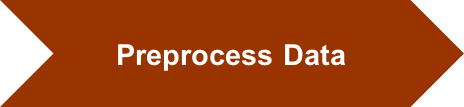

## Perform feature selection using Neighborhood Component Analysis

The last model performs pretty well, but it is too large for deployment on a small embedded device. Therefore, in this section we explore training a more compact model that uses only a subset of the 26 features, namely the features that have the majority of the predictive power. [Neighborhood Component Analysis](https://www.mathworks.com/help/stats/neighborhood-component-analysis.html) (NCA) is an automated approach for  selecting a small subset of features that carry information most relevant to the classification task while minimizing redudancy among selected features. 

runNCA = true;   % control whether to see NCA running or just load the selected features
    
if ~runNCA && exist('SelectedFeatures.mat')%#ok
    % Load saved array of selected feature indexes
    load('SelectedFeatures.mat')
    
else % Perform feature selection with neighborhood component analysis
    rng(1);
    % first, let's make sure we've split the data (in case we skipped the
    % programmatic model training sections above)
    if ~exist('training_set')
        [training_set, test_set] = splitDataSets(feature_table,0.3);
    end
    
    training_set=quan75_feature_table_infra;
    training_set.name=[];
        training_set.position=[];

    training_set.GroupCount=[];
    training_set75=quan75_feature_table(1:52,:);
    training_set75.name=[];
    training_set75.GroupCount=[];

    training_set.GroupCount_quan25_feature_table=[];
    training_set.GroupCount_quan75_feature_table=[];

    mdl = fscnca(table2array(training_set(:,6:end)),table2array(training_set(:,2)), 'Lambda', 0.001, 'Verbose', 1);
    
    % mdl = fscnca(table2array(training_set(:,2:73)), ...
   %     table2array(training_set(:,1)), 'Lambda', 0.001, 'Verbose', 0);
    mdl = fscnca(table2array(training_set(:,1:49)), table2array(training_set(:,50)),'Solver','sgd', 'Verbose', 1);
    selected_feature_indx = find(mdl.FeatureWeights > 0.1);  
    training_set_selected = training_set(:,[selected_feature_indx;50]);
%     mdl = fscnca(table2array(training_set(:,2:73)),table2array(training_set(:,1),'Solver','sgd','Verbose',1);
    mdl = fscnca(table2array(training_set(:,1:49)), table2array(training_set(:,50)),'Lambda', 0.005, 'Verbose', 1,'Standardize',true);

      mdl = fscnca(table2array(training_set(:,4:end)), table2array(training_set(:,2)), 'Lambda', 0.001);
    
    % Select features with weight above 1
    selected_feature_indx = find(mdl.FeatureWeights > 0.001)
    
    % Select features with weight above 1,
    
    selected_feature_indx75 = find(mdl75.FeatureWeights > 0.1);

    % Plot feature weights
    stem(mdl.FeatureWeights,'bo');
    
    % save for future reference
    save('SelectedFeatures', 'selected_feature_indx');
end

Unrecognized function or variable 'quan75_feature_table_infra'.

selected_feature_indx_new = [selected_feature_indx; 62]
new_set = [training_set(:,4:end), training_set(:,2)];

median_feature_table_selected = new_set(:,selected_feature_indx_new);
% Display list of selected features
disp(quad_feature_table.Properties.VariableNames(selected_feature_indx))

## 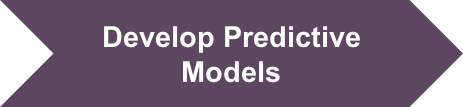

## Train model with selected features

To actually get a more compact model for deployment, we retrain the model using only selected features. Note how the file size decreased from 6G to 4G - maybe still not small enough, we could explore other models instead.

trainReducedModel = true;    % control whether to re-train this model or load it from a previous run

if trainReducedModel | ~exist('TrainedEnsembleModel_FeatSel.mat')%#ok
    % configure key parameters: cross validation, cost, and hyperparameter
    % tuning
    rng(1)
    cvp = cvpartition(length(subsample),'KFold',5);
    C = [0, 1; 1, 0];            % Assign higher cost for misclassification of abnormal heart sounds
    opts = struct('Optimizer','bayesopt','ShowPlots',true,'CVPartition',cvp,...
            'AcquisitionFunctionName','expected-improvement-plus','MaxObjectiveEvaluations',10);    
    
    % now we are ready to train...
%     trained_model_featsel = fitcensemble(training_set(subsample,selected_feature_indx),training_set.class(subsample),'Cost',C,...
%         'OptimizeHyperparameters',{'Method','NumLearningCycles','LearnRate'}, 'HyperparameterOptimizationOptions',opts)
%     
   

trained_model_featsel = fitcknn(training_set(subsample,selected_feature_indx),training_set.class(subsample),'Distance', 'Spearman', 'Exponent', [], 'NumNeighbors', 3, 'DistanceWeight', 'SquaredInverse', ...
    'Standardize', true, 'ClassNames', {'Abnormal'; 'Normal'},'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions', struct('AcquisitionFunctionName','expected-improvement-plus'));
    % save the model for later reference
    save('TrainedKNNModel_FeatSel', 'trained_model_featsel');
else
    load('TrainedKNNModel_FeatSel.mat')
end

% Predict class labels for the validation set using trained model
predicted_class_featsel = predict(trained_model_featsel, test_set(:,selected_feature_indx));

conf_mat_featsel = confusionmat(test_set.class, predicted_class_featsel);

conf_mat_per_featsel = conf_mat_featsel*100./sum(conf_mat_featsel, 2);

labels = {'Abnormal', 'Normal'};

% Visualize model performance
% probably custom AE version: heatmap(conf_mat_per_featsel, labels, labels, 1,'Colormap', 'red','ShowAllTicks',1,'UseLogColorMap',false,'Colorbar',true);
heatmap(labels,labels,conf_mat_per_featsel, 'Colormap', winter, 'ColorbarVisible','off');

## 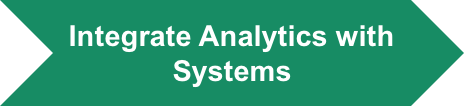

## Code Generation

Generate C code that takes recorded signal and sampling frequency as input and produces heart sound classification label as output. 

Instead of running codegen on the command line, if you were familiar with the Coder App and wanted to highlight this capability, you could bring up MATLAB Coder.

runCodegen = true;       % this typically takes several minutes
if runCodegen | ~exist('codegen/mex/classifyHeartSounds/classifyHeartSounds_mex')
    % Save trained model as a compact model for code generation
    %saveLearnerForCoder(trained_model_featsel,'HeartSoundClassificationModel');
    saveCompactModel(trained_model,'LungSoundClassificationModel');
    
    % Alternatively, execute the following auto-generated MATLAB script to generate C code (and mex file, in current directory)
    %classifyHeartSounds_codegen_script
    open classifyHeartSounds.m
    
    % saving the MEX file for future referene
    %copyfile codegen/mex/classifyHeartSounds/classifyHeartSounds_mex.mexw64 HelperFunctions
    %copyfile D:/classification_of_lung/HelperFunctions/codegen/mex/classifyHeartSounds/classifyHeartSounds_mex.mexw64 HelperFunctions
    coder
    

end


## Validate final model

Process a random subset of audio files from the validation set by the sample app. The app calls the mex version of the function "classifyHeartSounds"

plotPredictions

In this demonstration, you've learned:

- How to efficiently acccess and preprocess a large set of signal data by leveraging MATLAB's data store and parfor functionality

- Quickly assess the performance of various "traditional" classification models using the interactive Classification Learner

- Optimize models, both interactively and programmatically

- Reduce model size by selecting a small subset of the most predictive features

- Automatically generate corresponding prediction code and integrate that into a simple demo application

To further improve performance and dive yet deeper into what's possible with signal classification, you could explore:

- Generating better features using techniques like Wavelet scattering. [This example ](https://www.mathworks.com/help/wavelet/examples/ecg-signal-classification-using-wavelet-time-scattering.html)demonstrates that for an ECG signal, and in the "Bonus" section below we guide you through that process for the heart sound signal.

- Applying Deep Learning, like in [this example](https://www.mathworks.com/help/signal/examples/signal-classification-with-wavelet-analysis-and-convolutional-neural-networks.html) for the same ECG data as referenced above.

Final note: A seminar walking through an earlier version of this demo is available in [this video](https://www.mathworks.com/videos/essential-tools-for-machine-learning-1481139920800.html )*.*

*I would like to acknowledge that this demo has been conceived and implemented by Kirthi Devleker. Contact him for more information about applying machine and deep learning to signals, working in the spectral domain, and applying techniques such as Wavelet scattering.*

*Copyright 2019 The MathWorks, Inc.*

## Bonus section: Automated Features Extraction using Wavelet Scattering

Since the Heart Sound demo was created in 2017 and the Machine Learning eBook was written, a lot of progress in automated extraction of features has been made. One technique particularly suitable for signals is wavelet scattering.

Wavelet scattering derives, with minimal configuration (i.e. almost automatic), low-variance features from signal (and image) data for use in machine learning and deep learning application, as shown in the figure below.

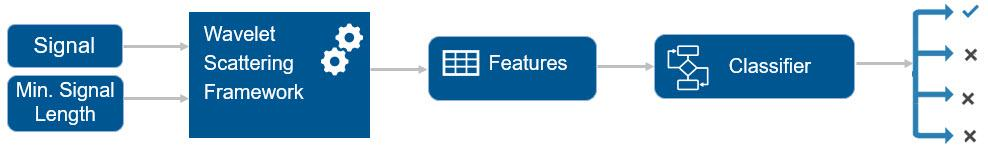

Wavelet transforms linearize small deformations such as dilations by separating the variations across different scales. For many natural signals, the wavelet transform also provides a sparse representation. While scattering can be compared to the filters implemented by the first layers of deep networks, an important distinctinon is that the wavelet filters are defined a priori as opposed to being learned. For more information about wavelet scattering, [click here](matlab:web(fullfile(docroot, 'wavelet/gs/wavelet-scattering.html'))).


% apply wavelet scattering to the whole training set (used also above)
N = 10000;         % min number of samples across whole data set (5 secs signal x 2,000 Hz)
sf = waveletScattering('SignalLength',N,'SamplingFrequency',2000);  % could try InvarianceScale 
[train_data,trainN] = extractWaveletFeatures(training_fds,sf, 10000,reference_table);


## Train a Classifier with Wavelet features

Above we generated 271 wavelet features automatically - all we had to do is manually is determine the minimum signal length. Training classifiers with these features works just like described above with the 27 manually "engineered" features.

With one quirk: since the wavelet transformation creates several observations from each signal, you cannot rely on random selection to "hold out" validation data, like provided conveniently in the Classification Learner. With random selection, you'd end up including some observations from the same signal in both training and validation data. Therefore, you have to manually "hold out" your test data for this exercise, and/or evaluate on a totally separate data set (like the validation data downloaded at the very beginning).

**TO DO:**

- Hold out a "test" set from train_data, for which you computed wavelet features above

- Using the Classification Learner, train a couple of models (skip "record_name" as predictor!)

- How much more accurate are they than your best result above?

- Apply feature selection to this model, and see how little accuracy you loose going back down to ~40 features

% This code will do #1, if you needed some help. You have a choice of
% holding out some data from the full training set, or process the
% validation data (which will be renamed test_set for compatibility with
% the accuracy measurement code further below)
if true
    % Hold out 0.3 as separate test set from the training data.
    % - Skipping column 1 which contains the record_name
    splitPt = round(height(train_data)*0.7);
    training_set = train_data(1:splitPt,2:273);
    test_set = train_data((splitPt+1):end,2:273);
    
    % Now train your model on "training_set" ...
else
    % Process the "official" validation set (provided by PhysioNet)
    
    % set up accessing validation data
    validation_dir = './Data/validation';
    reference_validation = importReferencefile([validation_dir '/REFERENCE.csv']);
    validation_fds = fileDatastore(validation_dir, 'ReadFcn', @importAudioFile, 'FileExtensions', '.wav');
    
    % compute wavelet features for validation data
    [validation_data,~] = extractWaveletFeatures(validation_fds,sf,N,reference_validation);
    
    % Use validation_data as your "test_set" below
    test_set = validation_data;
    test_set.record_name=[];      % ignore the record_name field
end

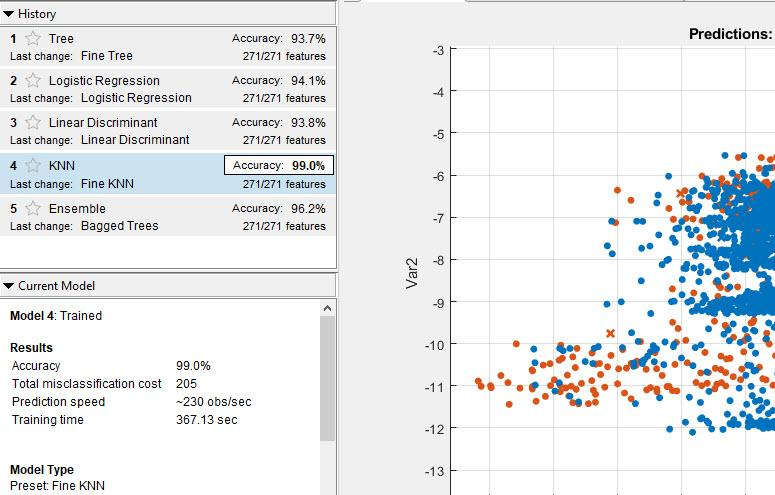

% After training your model on training_set (or the whole train_data),
% To evaluate accuracy on the unseen validation data:
% 1. Export your best model trained on wavelet features as "Compact" model
% 2. Modify the code below to calculate accuracy on "test_set"
%    (which may be the validation data, depending on how you prepared it)
% Shown below for KNN-model exported as "trainedModel"

predicted_wavelet = predict(trainedModel.ClassificationKNN, test_set);
conf_mat_wavelet = confusionmat(test_set.class, predicted_wavelet);
disp("Accuracy of the model based on automatically derived wavelet features:")
accuracy = (conf_mat_wavelet(1,1)+conf_mat_wavelet(2,2)) / size(test_set,1)

*Note: Expect accuracy of the model trained on the full set of 270+ wavelet features above 90% (we got 94% on held-out training data, but just 85% on validation).*